E = 0.08;
A = 1.0;
B = 0.2;
IO = 1;
tStart = 40;
tStop = 47;
I = @(t)IO*(t>tStart).*(t<tStop);

f1 =@(V,W,t) V - 1/3*V^3-W+I(t)

f1 = function_handle with value:
    @(V,W,t)V-1/3*V^3-W+I(t)


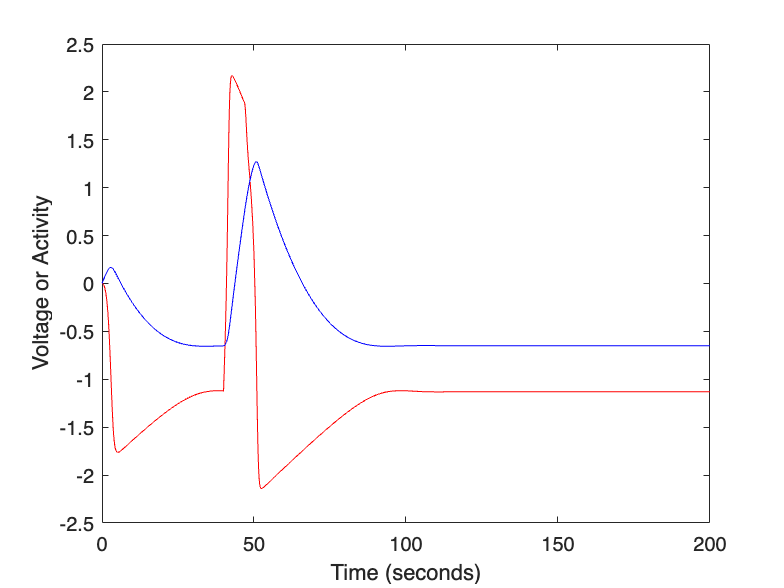

f2 =@(V,W,t) E*(V+A-B*W);

dxdt = @(t,x)[f1(x(1),x(2),t);
              f2(x(1),x(2),t)];
 

[T, X] = ode45(dxdt, [0,200], [0,0]);



plot(T,X(:,1),'-r');
hold on 
plot(T,X(:,2),'-b');
hold off
ylabel('Voltage or Activity')
xlabel('Time (seconds)')


% Question 1: confirmed oscillation
% Question 2: confired excitability for v=0.04 and w=-1.2
